**LINEARYZACJA**

**Cel ćwiczeń:** Celem ćwiczeń jest zrozumienie i praktyczne opanowanie procesu linearyzacji układów nieliniowych w otoczeniu punktu pracy. Zadanie polega na uzyskaniu liniowej aproksymacji na podstawie rozwinięcia funkcji opisującej dynamikę układu w szereg Taylora oraz interpretacji uzyskanych wyników. Analizowane będą zmienne odchyłkowe, które opisują małe zmiany zmiennych względem punktu pracy, oraz warunki, w których model liniowy jest wystarczająco dokładny. Ćwiczenie ma również na celu wykazanie znaczenia i ograniczeń modeli liniowych w analizie układów rzeczywistych oraz podkreślenie praktycznego zastosowania metod linearyzacji w klasycznej teorii sterowania.

**Wstęp:**

Linearyzacja jest jednym z kluczowych narzędzi stosowanych w teorii sterowania, pozwalającym na analizę i syntezę układów nieliniowych w uproszczonej, liniowej formie. Układy liniowe charakteryzują się prostym opisem matematycznym, w którym obowiązuje zasada superpozycji, jednak w rzeczywistości idealne układy liniowe nie istnieją. Liniowy model jest jedynie przybliżeniem, które można zastosować w ograniczonym obszarze zmiennych, gdzie układ zachowuje się z wystarczającą dokładnością liniowo. Z tego powodu, w praktyce stosuje się linearyzację, czyli proces aproksymacji układu nieliniowego przez zależności liniowe w otoczeniu wybranego punktu pracy. Proces ten bazuje na rozwinięciu w szereg Taylora i pominięciu członów wyższego rzędu, co prowadzi do uproszczonego modelu, który jest użyteczny dla małych odchyleń zmiennych wejściowych i wyjściowych od punktu pracy.

**1.Implementacja modelu nieliniowego**

W tej części zadania najpierw zdefiniowałem parametry układu: Q (strumień ciepła), w (wypływ cieczy), wi (dopływ cieczy), Ti (temperatura cieczy dopływającej), T0 (początkowa temperatura cieczy w zbiorniku) oraz V0 (początkowa objętość cieczy w zbiorniku). Następnie wykorzystałem funkcję ode45, aby numerycznie rozwiązać równania różniczkowe opisane w funkcji zbiornik_stan. Rozwiązanie zostało obliczone dla przedziału czasu od 0 do 799 sekund przy warunkach początkowych V0, T0, z parametrami wi, w, Ti i Q.

Otrzymane wyniki zapisałem w wektorach t (czas) oraz x, gdzie x(:,1) odpowiada objętości cieczy, a x(:,2) temperaturze cieczy. Następnie stworzyłem wykresy wyników przy użyciu funkcji plot w dwóch panelach.

W pierwszym podwykresie narysowałem objętość cieczy w funkcji czasu. Dodałem odpowiednie etykiety osi (Czas [s] i Objętość [m^3]) oraz tytuł.

W drugim podwykresie przedstawiłem temperaturę cieczy w funkcji czasu. Podobnie jak wcześniej, opisałem osie (Czas [s] i Temperatura [K]) oraz dodałem tytuł.

Całościowy tytuł wykresu ustawiłem za pomocą sgtitle jako Model nieliniowy.

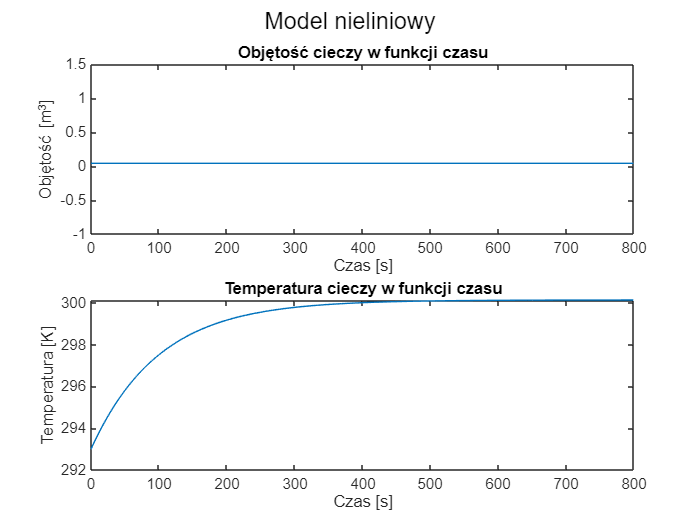

Q = 12000;
w = 0.4;
wi = 0.4;
Ti = 293;
T0 = 293;
V0 = 0.04;
[t,x] = ode45(@zbiornik_stan, 0:799, [V0,T0], [], wi, w, Ti, Q);

figure;
subplot(2,1,1);
plot(t,x(:,1))
xlabel("Czas [s]");
ylabel("Objętość [m^3]");
title('Objętość cieczy w funkcji czasu')

subplot(2,1,2);
plot(t,x(:,2))
xlabel("Czas [s]");
ylabel("Temperatura [K]");
sgtitle("Model nieliniowy");
title('Temperatura cieczy w funkcji czasu')

Wykresy zachowują się prawidłowo jak w przypadku poprzednich laboratoriów. Objętość cieczy w funkcji czasu jest stała natomiast temperatura zwiększa się logarytmicznie by przestać rosnąć w okolicy 303 stopni Kelwina.

**2. Implementacja modelu liniowego**

Najpierw zdefiniowałem początkowe warunki stanu X0, wejścia U0 oraz wyjścia Y0. Zablokowałem też za pośrednictwem IX, IU oraz IY stany, które miały pozostać stałe. W tej konfiguracji tylko parametr u(4) czyli Q- ciepło mogło się zmieniać. Następnie użyłem funkcji trim, aby znaleźć punkt pracy układu opisanego w modelu zbiornik_sys. Otrzymałem wartości zlinearyzowane wejść u.

Dalej wykorzystałem funkcję linmod, aby wyznaczyć macierze stanu A, B, C i D dla zlinearyzowanego modelu. Przy pomocy ss2tf przekształciłem te macierze na transmitancję układu w postaci licznika i mianownika.

Następnie zdefiniowałem dodatkowo warunki początkowe X_pocz i ustalone X_ust. Obliczyłem przesunięcie x0 jako różnicę między warunkami początkowymi a ustalonymi. Przygotowałem macierz wejść U z zerowymi wartościami na wszystkich kanałach, a następnie zasymulowałem odpowiedź układu przy użyciu funkcji lsim.

Otrzymane wyniki przedstawiłem na dwóch podwykresach. W pierwszym podwykresie narysowałem objętość cieczy w funkcji czasu, przesuniętą o wartość ustaloną X_ust(1).

W drugim podwykresie przedstawiłem temperaturę cieczy w funkcji czasu, przesuniętą o wartość ustaloną X_ust(2). 

Chociaż metoda użyta do linearyzacji jest przestarzała, ponieważ wyświetla stosowne ostrzeżenie, jednak nadal pozostaje zdatna do użycia i przedstawia całkiem dokładne przybliżenie liniowe przebiegu wykresu temperatury. Poniżej prezentuję konstrukcję użytego przeze mnie modelu simulinku (s-funkcji) zaimportowanej w funkcji trim.

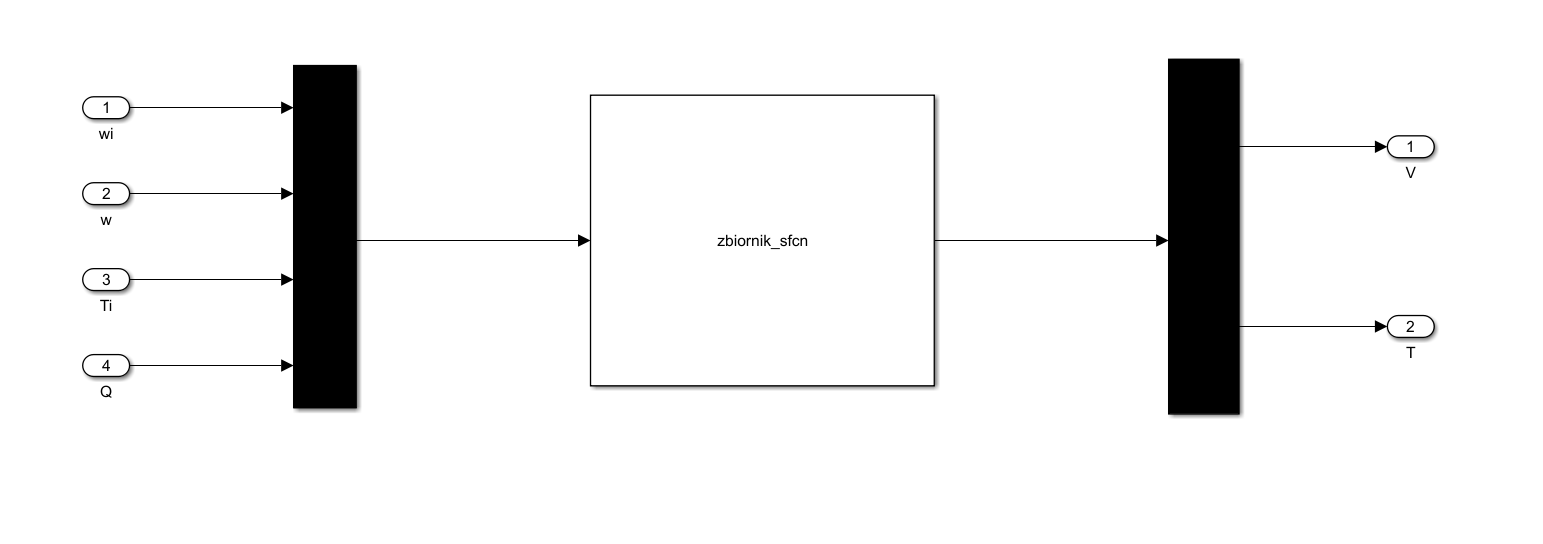

X0=[0.04;303];
U0=[0.4;0.4;293;12000];
Y0=[0.04;303];
IX=[]; 
IU=[1;2;3]; 
IY=[1;2];

[x,u,y1,dx] = trim('zbiornik_sys',X0,U0,Y0,IX,IU,IY,[],[], [1,1e-5]);

f-COUNT     MAX{g}         STEP  Procedures
    8    0.0285714            1   
   17    0.0328252          0.5  Hessian modified twice 
   31    0.0330837       0.0156  Hessian modified twice 
   47    0.0331525      0.00391  Hessian modified twice 
   60    0.0337081       0.0312  Hessian modified twice 
   72    0.0348969       0.0625  Hessian modified twice 
   83    0.0375005        0.125  Hessian modified twice 
   96    0.0381962       0.0312  Hessian modified twice 
  109    0.0388893       0.0312  Hessian modified twice 
  128    0.0389003     0.000488  Hessian modified twice 
  137    0.0516188          0.5  Hessian modified twice 
  148    0.0551484        0.125  Hessian modified twice 
  161    0.0560295       0.0312  Hessian modified twice 
  175    0.0564724       0.0156  Hessian modified twice 
  188    0.0573535       0.0312  Hessian modified twice 
  198    0.0646292         0.25  Hessian modified twice 
  212    0.0650589       0.0156  Hessian modified twice 
  220    

u

u = 1.0e+04 *

    0.0000
    0.0000
    0.0293
    1.6800


Tak jak oczekiwałem funkcja trim odpowiednio dobrała ciepło Q nadając mu wartość 16 800 . Taką moc trzeba doprowadzić do układu aby zwiększyć jego temperaturę o 10 K. Aby jednak moc została odpowiednio dobrana trzeba było zamienić czułość funkcyjną trim zmieniając jej options na czułość do 10^-5.

[A,B,C,D] = linmod('zbiornik_sys', x, u);
[licz,mian] = ss2tf(A,B,C,D,1);
printsys(licz,mian);

 
num(1)/den = 
 
   0.001 s + 1e-05
   ---------------
     s^2 + 0.01 s
 
num(2)/den = 
 
   -0.25 s - 1.3344e-15
   --------------------
       s^2 + 0.01 s


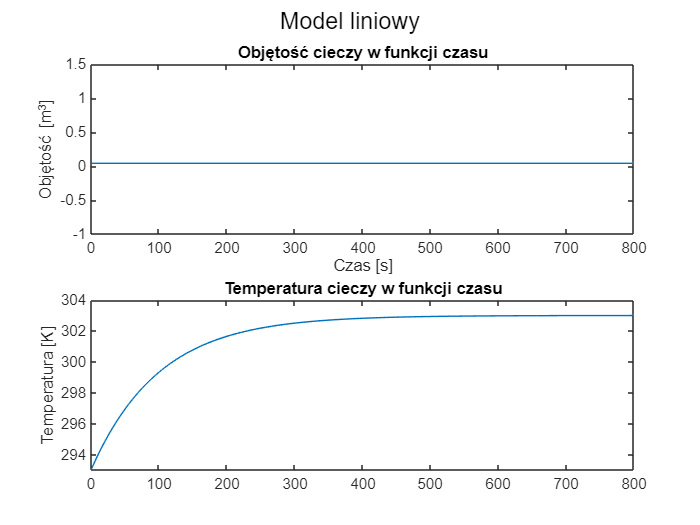

t = 0:799;
X_pocz = [0.04; 293];
X_ust = [0.04; 303];
x0 = X_pocz - X_ust;
U = zeros(length(t), 4);
y1 = lsim(A,B,C,D,U,t,x0);
figure;
subplot(2,1,1),plot(t,y1(:,1) + X_ust(1)),title('Objętość cieczy w funkcji czasu'),xlabel('Czas [s]'),ylabel('Objętość [m^3]')
subplot(2,1,2),plot(t,y1(:,2) + X_ust(2)),title('Temperatura cieczy w funkcji czasu'),ylabel('Czas [s]'), ylabel('Temperatura [K]')
sgtitle("Model liniowy")

Wyniki wykresów mają porównywalny przebieg i potwierdzają poprawność metody linearyzacji. Jest ona znacznie prostsza w implementacji szczególnie gdy mamy do czynienia z problemem opisanym przez wiele równań różniczkowych, nie tak prostym jak w naszym przypadku. 

**3. Porównywanie błędów**

**a) dla stanu ustalonego **

W tym miejscu miałem za zadanie porównać jak odbiega wykres nieliniowy od liniowego tym samym znajdując błąd linearyzacji. Całość zaprezentowałem na dwóch wykresach, z których pierwszy prezentował po prostu porównanie dwóch przebiegów natomiast drugi dla każdej chwili czasowej odejmował wartość temperatury obliczonej nieliniowo od temperatury obliczonej liniowo.

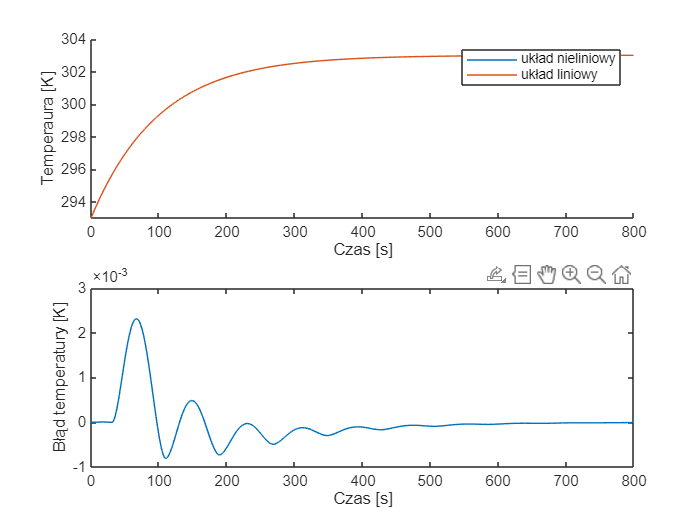

X0=[0.04;303];
U0=[0.4;0.4;293;12000];
Y0=[0.04;303];
IX=[]; 
IU=[1;2;3]; 
IY=[1;2];
Q = 16800;
w = 0.4;
wi = 0.4;
Ti = 293;
T0 = 293;
V0 = 0.04;
t_lin= 0:799;
X_ust = [0.04; 303];
[x,u,y,dx] = trim('zbiornik_sys',X0,U0,Y0,IX,IU,IY,[],[], [1,1e-5]);
[t_notlin,x_notlin] = ode45(@zbiornik_stan, 0:799, [V0,T0], [], wi, w, Ti, Q);
figure
subplot(2,1,1);
hold on
plot(t_notlin, x_notlin(:,2));
plot(t,y1(:,2) + X_ust(2))
hold off
legend("układ nieliniowy", "układ liniowy");
xlabel("Czas [s]");
ylabel("Temperaura [K]");
subplot(2,1,2);
plot(t_notlin, x_notlin(:,2) - (y1(:,2) + X_ust(2)));
xlabel("Czas [s]");
ylabel("Błąd temperatury [K]");

Jak widać na powyższych wykresach błąd linearyzacji temperatury jest stosunkowo niewielki w stanie ustalonym dla stałej objętości. Można zauważyć że podobnie jak wykres również się stabilizuje dla bardzo małej wartości praktycznie równej 0. Stąd można wywnioskować, że jest to sprawdzona metoda predykcji zachowania układu w czasie.

**b) dla stanu nieustalonego**

W tym podpunkcie dołożyłem zmieniającą się stale rosnącą objętość. Wykonałem odpowiednie przekształcenia wykresów jednak, poza zmianą U niewiele zmieniłem w reszcie kodu. Dalej porównywałem tak samo w subplocie wykresy przebiegów oraz błędu linearyzacji.

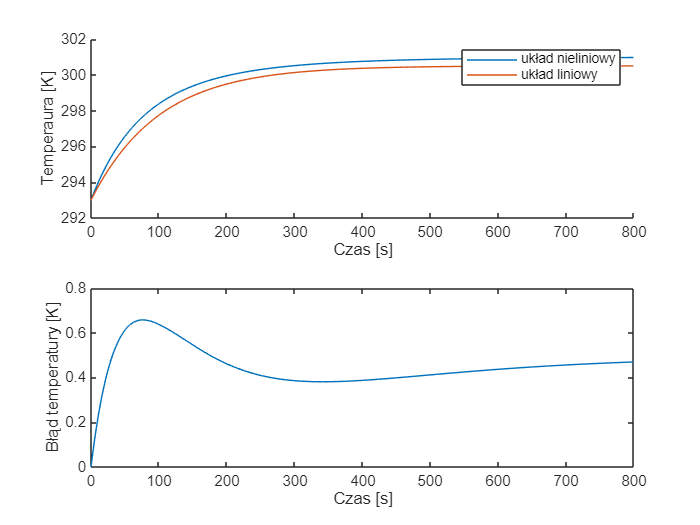

wi = 0.5;
w = 0.4;
U(:,1) = 0.1;
y2 = lsim(A,B,C,D,U,t,x0);
[t_notlin,x_notlin] = ode45(@zbiornik_stan, 0:799, [V0,T0], [], wi, w, Ti, Q);
figure
subplot(2,1,1);
hold on
plot(t_notlin, x_notlin(:,2));
plot(t_notlin,y2(:,2) + X_ust(2))
hold off
legend("układ nieliniowy", "układ liniowy");
xlabel("Czas [s]");
ylabel("Temperaura [K]");
subplot(2,1,2);
plot(t_notlin, x_notlin(:,2) - (y2(:,2) + X_ust(2)))
xlabel("Czas [s]");
ylabel("Błąd temperatury [K]");

W tym wypadku sprawa okazuje się być mniej ciekawa. Wykresy w pierwszym przypadku już da się odróżnić gołym okiem na co wskazuje błąd temperatury. Wartości błędu osiągają swoje maksimum przed 100 sekundą jako nieco ponad 0.6 Kelwin. Nie są to wartości bardzo duże i nadal układ dobrze się sprawdza charakterystyki zachowań temperatury w czasie. Warto mieć jednak świadomość istnienia błędu, który już nie jest tak bliski zeru jak dla stanu ustalonego.

**Podsumowanie:**

Linearyzacja stanowi skuteczne narzędzie do opisu nieliniowych układów dynamicznych w pobliżu punktu pracy, szczególnie dla małych odchyleń zmiennych stanu. Dokładność tego podejścia zależy jednak od wielkości zmian w układzie, a jego ograniczenia są bardziej widoczne w stanach nieustalonych, gdzie nieliniowości mają większy wpływ na wyniki. W praktyce należy zatem świadomie stosować modele liniowe, uwzględniając zakres ich stosowalności i potencjalne błędy aproksymacji.